# create downsampled vector of all aluminum times without the artifact times

run(params_path)

experiment = auditory_ephys_exp(params_path);

Choose csv file for the whisking camera
Choose csv file for the face camera


data = load_open_ephys_binary([exp_path,'/experiment1/recording1/structure.oebin'],'continuous',1,'mmap');
%aud_data = data.Data.Data.mapped(32 + mic,:)

% find time samples in video based on whiskers for both whiskers and face
whiskingStart = experiment.Cams.whsiking.csv_start_frame

whiskingStart = 400

expLength = length(data.Data.Data.mapped)

expLength = 52406629

whiskingEnd = find(experiment.Cams.whsiking.csv_aligned_frames < expLength);
whiskingEnd = whiskingEnd(end)

whiskingEnd = 697613

whiskingVector = [whiskingStart:whiskingEnd]

whiskingVector =    400   401   402   403   404   405   406   407   408   409   410   411   412   413   414   415   416   417   418   419   420   421   422   423   424   425   426   427   428   429   430   431   432   433   434   435   436   437   438   439   440   441   442   443   444   445   446   447   448   449


sampleVector = experiment.Cams.whsiking.csv_aligned_frames(whiskingVector)

sampleVector =        74285
       74442
       74489
       74572
       74642
       74717
       74803
       74870
       74943
       75026



[~,faceStart] = min(abs(experiment.Cams.face.csv_aligned_frames - sampleVector(1)))

faceStart = 99

faceVector = [faceStart:faceStart+length(whiskingVector)-1]

faceVector =     99   100   101   102   103   104   105   106   107   108   109   110   111   112   113   114   115   116   117   118   119   120   121   122   123   124   125   126   127   128   129   130   131   132   133   134   135   136   137   138   139   140   141   142   143   144   145   146   147   148


### If there is a mistake in extracting condition changes, please correct it here

- `Check how many were missed`

- `Check the condition missed class with the camera`

- `identify the condition change in the sound `

- `Split the conditions and clasiffy them in experiment.conditions`

% if needed use this space for corrections
%  experiment.Conditions.condition_classification = [experiment.Conditions.condition_classification(1:4);1;experiment.Conditions.condition_classification(5:end)]
%  experiment.Conditions.all_changes = [experiment.Conditions.all_changes(1:4);g;experiment.Conditions.all_changes(5:end)]

% Extract aluminum times
artifactStart = experiment.Conditions.artifact_times(2) * 30

experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB109_904'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: []
         predictionModel: []
                   PSTHs: []
          predictedSound: []
            evokedEvents: [1×1 struct]


artifactEnd = experiment.Conditions.artifact_times(1) * 30

experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB109_904'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: []
         predictionModel: []
                   PSTHs: []
          predictedSound: []
            evokedEvents: [1×1 struct]


all_times = [experiment.Conditions.all_changes + artifactStart,[experiment.Conditions.all_changes(2:end);sampleVector(end)]-artifactEnd]
aluminumTimes = all_times(experiment.Conditions.condition_classification == 1,:)
% create idx vector for aluminum

artifactStart = 75000

aluminumInd = []

artifactEnd = 90000

for al = 1:length(aluminumTimes)

all_times = 26×2 int64 matrix
    4780131    6504689
    6669689    8394247
    8559247   10271807
   10436807   12155530
   12320530   14032930
   14197930   15910492
   16075492   17800051
   17965051   19677656
   19842656   21567216
   21732216   23456776


    tempInd = find(sampleVector > aluminumTimes(al,1) & sampleVector < aluminumTimes(al,2))

aluminumTimes = 10×2 int64 matrix
   10436807   12155530
   12320530   14032930
   16075492   17800051
   19842656   21567216
   25499338   27217901
   31150025   32874585
   34917191   36629753
   36794753   38513317
   48102128   49814734
   49979734   51704294


    aluminumInd = [aluminumInd;tempInd]
end


aluminumInd =

     []



% create samplevector for aluminum
aluminumVector = sampleVector(aluminumInd)
% create video frame whisker vector
aluminumWhiskerVector = whiskingVector(aluminumInd)'

tempInd =       138069
      138070
      138071
      138072
      138073
      138074
      138075
      138076
      138077
      138078


aluminumInd =       138069
      138070
      138071
      138072
      138073
      138074
      138075
      138076
      138077
      138078


tempInd =       163166
      163167
      163168
      163169
      163170
      163171
      163172
      163173
      163174
      163175


aluminumInd =       138069
      138070
      138071
      138072
      138073
      138074
      138075
      138076
      138077
      138078


tempInd =       213195
      213196
      213197
      213198
      213199
      213200
      213201
      213202
      213203
      213204


aluminumInd =       138069
      138070
      138071
      138072
      138073
      138074
      138075
      138076
      138077
      138078


tempInd =       263387
      263388
      263389
      263390
      263391
      263392
      263393
      263394
      263395
      263396


aluminumInd =       138069
      138070
      138071
      138072
      138073
      138074
      138075
      138076
      138077
      138078


tempInd =       338744
      338745
      338746
      338747
      338748
      338749
      338750
      338751
      338752
      338753


aluminumInd =       138069
      138070
      138071
      138072
      138073
      138074
      138075
      138076
      138077
      138078


tempInd =       414026
      414027
      414028
      414029
      414030
      414031
      414032
      414033
      414034
      414035


aluminumInd =       138069
      138070
      138071
      138072
      138073
      138074
      138075
      138076
      138077
      138078


tempInd =       464213
      464214
      464215
      464216
      464217
      464218
      464219
      464220
      464221
      464222


aluminumInd =       138069
      138070
      138071
      138072
      138073
      138074
      138075
      138076
      138077
      138078


tempInd =       489214
      489215
      489216
      489217
      489218
      489219
      489220
      489221
      489222
      489223


aluminumInd =       138069
      138070
      138071
      138072
      138073
      138074
      138075
      138076
      138077
      138078


tempInd =       639865
      639866
      639867
      639868
      639869
      639870
      639871
      639872
      639873
      639874


aluminumInd =       138069
      138070
      138071
      138072
      138073
      138074
      138075
      138076
      138077
      138078


tempInd =       664882
      664883
      664884
      664885
      664886
      664887
      664888
      664889
      664890
      664891


aluminumInd =       138069
      138070
      138071
      138072
      138073
      138074
      138075
      138076
      138077
      138078


% create video frame face vector
aluminumFaceVector = faceVector(aluminumInd)'

## **create matrix for prediction with linear regression**

### **The model is a matrix with the following rows as variables and columuns as observations:**

- ** Encoder**

- **whiskingMotion_1**

- **whisking motSVD_0 (10 first)**

- **whisking motSVD_1 (10 first)**

- **faceMotion_1**

- **face motSVD_1 (10 first)**

- **Running from face camera**

**Predictions should be done on a matrix ordered the same why**

**The output will be a vector of the sound from open ephys sampled by the sampleVector and threshold **

% get the sound vector 

aluminumVector =     10436881
    10436965
    10437048
    10437120
    10437179
    10437267
    10437343
    10437411
    10437485
    10437567


aud_data = data.Data.Data.mapped(34,:)

mkdir analysis

aluminumWhiskerVector =       138468
      138469
      138470
      138471
      138472
      138473
      138474
      138475
      138476
      138477


cd analysis
audiowrite("aud_data.wav",aud_data,30000)

aluminumFaceVector =       138167
      138168
      138169
      138170
      138171
      138172
      138173
      138174
      138175
      138176


% clean artifacts clipping
figure; plot(aud_data(10000000:20000000))

aud_data = 1×52406629 int16 row vector
   468   502   463   444   478   472   457   459   457   427   501   451   461   445   438   460   492   417   483   503   497   499   507   471   411   499   491   443   477   429   441   423   417   427   467   493   453   433   443   461   391   397   451   480   503   499   437   456   473   482


for art = 1:length(all_times)
    chg_time = experiment.Conditions.all_changes(art);
    aud_data(chg_time-artifactEnd:chg_time+artifactStart) = median(aud_data);
end

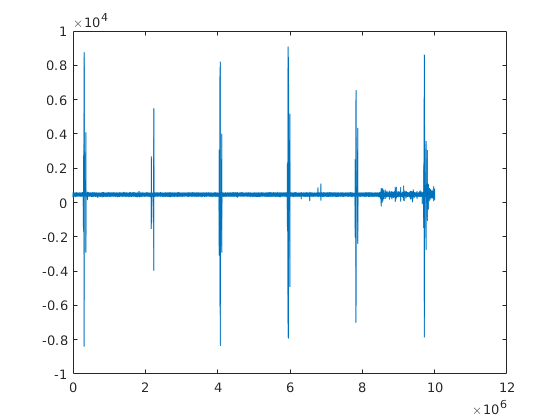

hold on; plot(aud_data(10000000:20000000))

%filter data and keep just the aluminum sound componenets
[b,a] = cheby1(5,20,[5000]/15000,'high');
aud_data_filt = filtfilt(b,a,double(aud_data));
figure; plot(aud_data_filt(10000000:20000000))

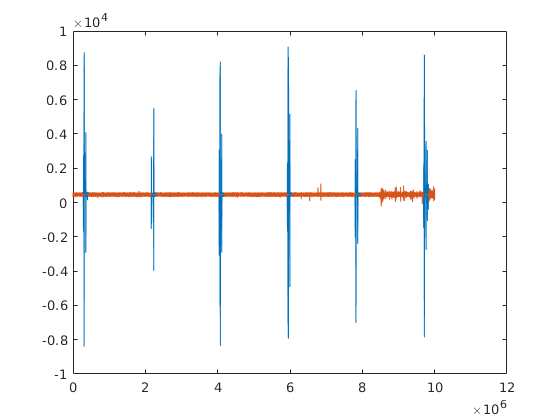

% envelope aud_data
aud_data_env = envelope(aud_data_filt,300,"analytic");

figure; plot([1:10000001]/30000,aud_data_filt(10000000:20000000))
hold on; plot([1:10000001]/30000,aud_data_env(10000000:20000000))

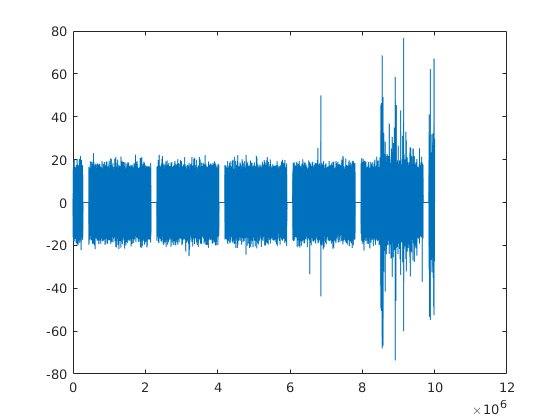

% filter envelope to gte only slow changes

[bn,an] = butter(3,[80]/15000,"low");
aud_data_env = filtfilt(bn,an,double(aud_data_env));

aud_data_cleaned = normalize(aud_data_env,'range',[0,1])

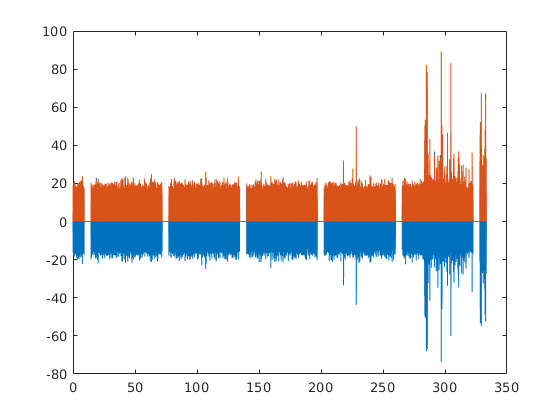

figure;plot([1:10000001]/30000,aud_data_cleaned(10000000:20000000),'LineWidth',2)


% clean data below threshold
%aud_data_cleaned(aud_data_cleaned<0.11) = median(aud_data_cleaned);


figure; plot([1:10000001]/30000,aud_data_cleaned(10000000:20000000),'LineWidth',2)



aud_data_cleaned =     0.0510    0.0511    0.0511    0.0511    0.0511    0.0512    0.0512    0.0512    0.0513    0.0513    0.0513    0.0514    0.0514    0.0514    0.0515    0.0515    0.0515    0.0516    0.0516    0.0517    0.0517    0.0517    0.0518    0.0518    0.0518    0.0519    0.0519    0.0519    0.0520    0.0520    0.0521    0.0521    0.0521    0.0522    0.0522    0.0523    0.0523    0.0524    0.0524    0.0524    0.0525    0.0525    0.0526    0.0526    0.0527    0.0527    0.0528    0.0528    0.0529    0.0529


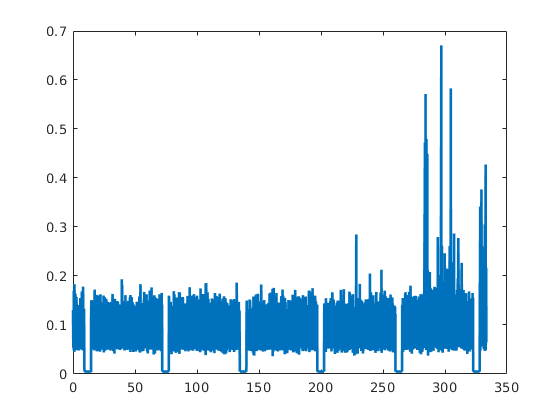

experiment.sound_events.fullSound = aud_data;

experiment.sound_events.fullSoundCleaned = aud_data_cleaned;

aud_data_Alum = aud_data_cleaned(aluminumVector)

%aud_data_cleaned(aud_data_cleaned < 0.1) = 0

figure; plot(aud_data_Alum)

cd analysis/
save('FVB109_904.mat',"experiment")

% get encoder data and high pass filter 
encoder_data = data.Data.Data.mapped(32 + encoder,:)

aud_data_Alum =     0.0893    0.1256    0.1165    0.0884    0.0769    0.0918    0.1097    0.1128    0.0994    0.0809    0.0806    0.0925    0.1007    0.0893    0.0747    0.0680    0.0666    0.0664    0.0692    0.0723    0.0726    0.0722    0.0677    0.0603    0.0716    0.0997    0.1350    0.1309    0.1031    0.0888    0.1012    0.1135    0.1065    0.0909    0.0843    0.0856    0.0848    0.0818    0.0705    0.0647    0.0759    0.1001    0.1220    0.1139    0.0977    0.0984    0.0995    0.0755    0.0524    0.0492


[b,a] = butter(3,[2 400]/15000,'bandpass')
encoder_data = filtfilt(b,a,double(encoder_data))

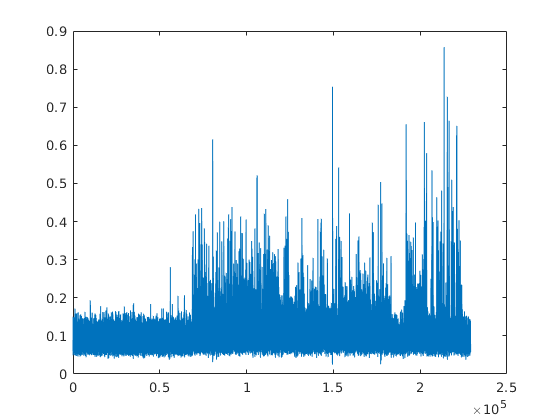

figure; plot(encoder_data)

encoder_data = envelope(normalize(encoder_data))

% import the whisking moiton vectors
[file,path] = uigetfile();
cd(path)
load(file,'motSVD_1','motion_1')

encoder_data = 1×52406629 int16 row vector
   860   856   845   861   855   875   879   865   875   871   869   861   865   875   870   863   867   861   873   864   857   859   862   870   859   875   883   879   877   849   869   873   875   877   867   863   865   865   859   865   866   867   857   878   883   871   879   867   875   875


% add encoder to the modal and prediction matrices

b = 	1.0e+-3 *

    0.0667         0   -0.2002         0    0.2002         0   -0.0667


a =     1.0000   -5.8332   14.1799  -18.3866   13.4130   -5.2194    0.8464


modelMatrix = encoder_data(aluminumVector)'

encoder_data = 	1.0e+04 *

    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011    0.0011    0.0011    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013


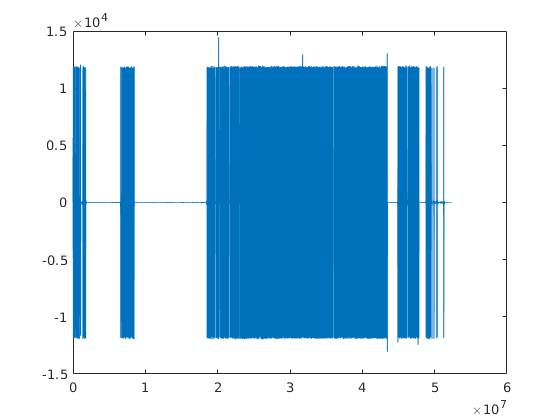

predictionMatrix = encoder_data(sampleVector)'


motSVD_1(:,1:250) = envelope(normalize(motSVD_1(:,1:250)))

encoder_data =     0.0105    0.0090    0.0092    0.0089    0.0090    0.0089    0.0090    0.0089    0.0090    0.0090    0.0091    0.0090    0.0091    0.0091    0.0091    0.0091    0.0091    0.0091    0.0092    0.0091    0.0092    0.0091    0.0091    0.0091    0.0091    0.0091    0.0091    0.0091    0.0091    0.0091    0.0091    0.0090    0.0090    0.0090    0.0090    0.0090    0.0090    0.0090    0.0090    0.0090    0.0090    0.0090    0.0091    0.0091    0.0091    0.0091    0.0091    0.0092    0.0092    0.0092


motion_1 = envelope(normalize(motion_1))

modelMatrix(:,2) = motion_1(aluminumWhiskerVector)
predictionMatrix(:,2) = motion_1(whiskingVector)
modelMatrix(:,3:252) = motSVD_1(aluminumWhiskerVector,1:250)
predictionMatrix(:,3:252) = motSVD_1(whiskingVector,1:250)


% save the model and prediction vectors 

modelMatrix =     0.0046
    0.0024
    0.0031
    0.0028
    0.0025
    0.0041
    0.0014
    0.0028
    0.0019
    0.0020


predictionMatrix =     0.2304
    0.2258
    0.2227
    0.2192
    0.2175
    0.2136
    0.2124
    0.2097
    0.2051
    0.2041


save('model_matrices.mat','modelMatrix',"aud_data_Alum",'predictionMatrix','sampleVector','aluminumWhiskerVector')


clearvars -except modelMatrix aud_data_Alum predictionMatrix sampleVector aluminumWhiskerVector

motSVD_1 = 697703×500 single matrix
    5.7744    4.8655    2.3034    0.8539    3.2886    0.6027    2.1191    4.2271    6.0151    1.6373    0.5951    1.2524    0.8496    0.9045    0.3658    1.2092    2.7827    0.7779    2.9031    1.9292    1.1989    0.6048    0.5846    1.3808    1.1736    0.9345    0.7216    1.2131    2.5862    0.9045    1.0311    1.8164    1.0957    0.2025    1.1538    0.4566    2.6982    0.7762    0.4747    2.0518    0.3871    0.8760    1.9330    1.3601    0.9033    1.2268    1.1746    0.9158    0.3219    1.6144
    5.4578    3.7532    1.0557    0.5625    1.9226    0.5576    2.3576    3.3857    3.8890    2.4889    0.5717    1.1788    2.7991    0.3337    0.4528    2.3156    0.7424    0.2895    2.8442    1.4725    2.9023    0.7316    0.7781    1.0847    1.9770    2.9331    3.5660    0.8215    2.0187    0.8729    2.8432    1.4700    1.7098    0.4467    1.6760    1.4483    1.7360    0.4938    1.0279    1.5350    0.4110    0.6624    2.5835    1.8508    0.8992    1.6750   

figure; plot(aud_data_Alum)

motion_1 = 1×697703 single row vector
    6.0548    5.2420    4.7688    4.2622    3.6079    3.1883    3.5010    4.7849    4.9519    4.5327    4.0127    3.6407    2.7941    2.4615    2.3156    2.9409    3.3900    4.1468    4.0950    4.4075    4.2755    3.9809    3.8912    2.8372    2.5551    2.8295    2.8629    3.5744    4.4134    4.4515    3.9427    3.6668    3.3484    3.0789    2.5651    2.3853    1.8929    2.6094    3.1510    3.3296    3.6385    3.9931    3.7614    3.2290    2.7230    3.0231    3.6627    4.5211    4.5807    3.9554


hold on; plot(modelMatrix(:,1)/50)

modelMatrix =     0.0046    1.0047
    0.0024    1.0456
    0.0031    1.1227
    0.0028    1.0930
    0.0025    1.0715
    0.0041    1.1476
    0.0014    1.1705
    0.0028    1.1469
    0.0019    1.1141
    0.0020    1.1497


modelMatrix(:,253) = aud_data_Alum

predictionMatrix =     0.2304    1.8252
    0.2258    1.6902
    0.2227    1.5999
    0.2192    4.8296
    0.2175    5.3656
    0.2136    2.9343
    0.2124    4.0931
    0.2097    3.8230
    0.2051    4.2275
    0.2041    4.7572


%Annotate quiet periods and movement periods

modelMatrix =     0.0046    1.0047    1.0742    0.3614    0.3190    0.2023    0.1074    0.2154    0.1033    0.1332    0.3113    0.1185    0.3783    0.0431    0.2105    0.0801    0.0845    0.1045    0.1996    0.1961    0.4234    0.0474    0.0507    0.2333    0.2161    0.3659    0.1287    0.2148    0.0886    0.4134    0.1749    0.3598    0.2346    0.3418    0.2440    0.0243    0.2131    0.1609    0.0624    0.1746    0.1596    0.2159    0.2144    0.1185    0.2664    0.2856    0.3108    0.2383    0.3627    0.2018
    0.0024    1.0456    1.0540    0.3239    0.5088    0.1172    0.0387    0.2943    0.1119    0.1235    0.2422    0.0232    0.2467    0.1065    0.1941    0.0770    0.1541    0.1224    0.1714    0.1383    0.2237    0.2164    0.0268    0.3276    0.2184    0.3253    0.1403    0.3019    0.1436    0.2419    0.0564    0.3702    0.1930    0.0409    0.2004    0.2511    0.0861    0.1924    0.0972    0.0649    0.1517    0.2843    0.0617    0.0509    0.0315    0.0406    0.4454    0.2229    0

%Annotate quiet periods and movement periods

predictionMatrix =     0.2304    1.8252    1.1970    4.2271    7.0784    1.5565    4.1976    6.7353    3.6601    1.4260    4.1895    2.3567    6.2054    2.8600    0.5937    1.1638    1.4673    2.8735    4.1481    1.7973    0.9843    1.3355    1.8161    2.1569    3.9042    5.2470    6.4976    3.7982    0.8824    2.4378    1.9664    4.1891    4.3926    1.0132    0.9380    1.1989    1.0912    2.9340    5.3673    1.9124    2.2593    2.9065    2.1497    3.2326    1.5824    3.9845    4.7667    1.0818    0.7146    1.8368
    0.2258    1.6902    2.0282    3.9418    5.7052    2.4466    4.1454    5.5833    3.8768    1.4515    0.9590    2.9731    6.1583    2.7280    1.4464    0.5845    1.0996    3.6035    5.3951    0.9970    1.6654    1.5401    1.7016    0.5716    0.8469    2.8645    5.6758    1.8553    1.1252    5.1542    2.8473    0.5820    1.0583    1.0120    3.5641    2.9549    0.6164    1.4446    2.8763    3.2027    3.3410    2.5039    2.3870    1.3399    5.0456    2.4651    0.4852    3.0519

movement_times = [68701,183210;191871,203690;206091,207420;209481,223930]
quiet_times = [1,68700;183211,191870;203691,206090;207421,209480;223931,229040]

% split modelMatrix to quiet and movement periods and reduce the below
% threshold movement
modelClean = [];
model_quiet =[];
for tt = 1:5
        modelTemp = modelMatrix(quiet_times(tt,1):quiet_times(tt,2),:);
        mm = cvpartition(length(modelTemp),"HoldOut",0.3);
        idxquiet = test(mm);

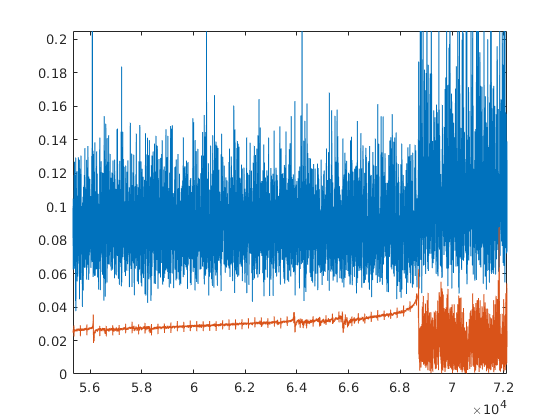

        sum(idxquiet)
        modelTemp = modelTemp(idxquiet,:);

        aud_below = modelTemp(:,253) < 0.2;
        modelTemp(aud_below,253) = 0;

modelMatrix =     0.0046    1.0047    1.0742    0.3614    0.3190    0.2023    0.1074    0.2154    0.1033    0.1332    0.3113    0.1185    0.3783    0.0431    0.2105    0.0801    0.0845    0.1045    0.1996    0.1961    0.4234    0.0474    0.0507    0.2333    0.2161    0.3659    0.1287    0.2148    0.0886    0.4134    0.1749    0.3598    0.2346    0.3418    0.2440    0.0243    0.2131    0.1609    0.0624    0.1746    0.1596    0.2159    0.2144    0.1185    0.2664    0.2856    0.3108    0.2383    0.3627    0.2018
    0.0024    1.0456    1.0540    0.3239    0.5088    0.1172    0.0387    0.2943    0.1119    0.1235    0.2422    0.0232    0.2467    0.1065    0.1941    0.0770    0.1541    0.1224    0.1714    0.1383    0.2237    0.2164    0.0268    0.3276    0.2184    0.3253    0.1403    0.3019    0.1436    0.2419    0.0564    0.3702    0.1930    0.0409    0.2004    0.2511    0.0861    0.1924    0.0972    0.0649    0.1517    0.2843    0.0617    0.0509    0.0315    0.0406    0.4454    0.2229    0

        modelClean = [modelClean;modelTemp];
    
    if tt<4
        model_temp = modelMatrix(movement_times(tt,1):movement_times(tt,2),:);

movement_times =        68701      183210
      191871      203690
      206091      207420
      209481      223930


        aud_below = model_temp(:,253) < 0.18;

quiet_times =            1       68700
      183211      191870
      203691      206090
      207421      209480
      223931      229040


        modelClean = [modelClean;model_temp];
%     sum(aud_below)
%     model_temp = model_temp(aud_below,:);
    end
end

figure; 
plot(modelClean(:,253))

%modelClean(:,1:252) = envelope(normalize(modelClean(:,1:252)))


ans = 20610

ans = 2598

ans = 720

ans = 618

ans = 1533

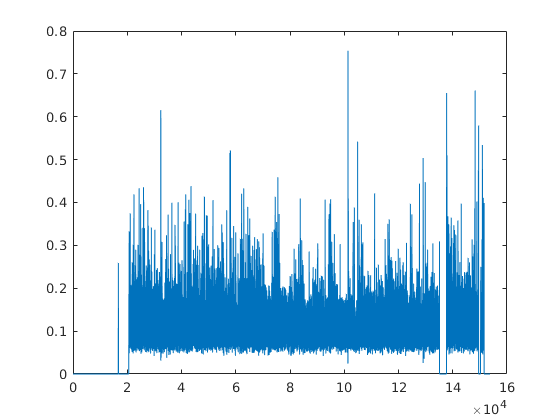

figure;
plot(modelClean(:,1))

%predictionMatrix = envelope(normalize(predictionMatrix))

figure;
plot(predictionMatrix(:,100))

save("modelclean.mat","modelClean","predictionMatrix","sampleVector")

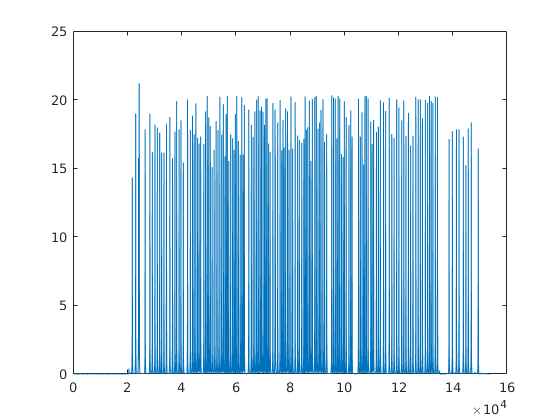

clearvars -except   modelClean predictionMatrix sampleVector

data_length = length(modelClean(:,1))
data_length/400

data10 = round(0.1*data_length)
data10/400
lengthTestSection = round(data10/5)

testStarts = randperm(data_length,5)
testEnds = testStarts+lengthTestSection
idxTest =[];
for tt = 1:5
    testTemp = testStarts(tt):testEnds(tt)

data_length = 153739

    idxTest = [idxTest,testTemp]

ans = 384.3475

end

idxTest = ismember(1:data_length,idxTest)

data10 = 15374

idxTrain = ~idxTest

ans = 38.4350

    % split data to train test

lengthTestSection = 3075

modelTrain = modelClean(~idxTest,:)
modelTest = modelClean(idxTest,:)

testStarts =        72629       49899       44327       27665       30977


testEnds =        75704       52974       47402       30740       34052


%aud_data_Train = aud_data_Alum(idxTrain)
%aud_data_test = aud_data_Alum(idxTest)

testTemp =        72629       72630       72631       72632       72633       72634       72635       72636       72637       72638       72639       72640       72641       72642       72643       72644       72645       72646       72647       72648       72649       72650       72651       72652       72653       72654       72655       72656       72657       72658       72659       72660       72661       72662       72663       72664       72665       72666       72667       72668       72669       72670       72671       72672       72673       72674       72675       72676       72677       72678


idxTest =        72629       72630       72631       72632       72633       72634       72635       72636       72637       72638       72639       72640       72641       72642       72643       72644       72645       72646       72647       72648       72649       72650       72651       72652       72653       72654       72655       72656       72657       72658       72659       72660       72661       72662       72663       72664       72665       72666       72667       72668       72669       72670       72671       72672       72673       72674       72675       72676       72677       72678


testTemp =        49899       49900       49901       49902       49903       49904       49905       49906       49907       49908       49909       49910       49911       49912       49913       49914       49915       49916       49917       49918       49919       49920       49921       49922       49923       49924       49925       49926       49927       49928       49929       49930       49931       49932       49933       49934       49935       49936       49937       49938       49939       49940       49941       49942       49943       49944       49945       49946       49947       49948


idxTest =        72629       72630       72631       72632       72633       72634       72635       72636       72637       72638       72639       72640       72641       72642       72643       72644       72645       72646       72647       72648       72649       72650       72651       72652       72653       72654       72655       72656       72657       72658       72659       72660       72661       72662       72663       72664       72665       72666       72667       72668       72669       72670       72671       72672       72673       72674       72675       72676       72677       72678


testTemp =        44327       44328       44329       44330       44331       44332       44333       44334       44335       44336       44337       44338       44339       44340       44341       44342       44343       44344       44345       44346       44347       44348       44349       44350       44351       44352       44353       44354       44355       44356       44357       44358       44359       44360       44361       44362       44363       44364       44365       44366       44367       44368       44369       44370       44371       44372       44373       44374       44375       44376


idxTest =        72629       72630       72631       72632       72633       72634       72635       72636       72637       72638       72639       72640       72641       72642       72643       72644       72645       72646       72647       72648       72649       72650       72651       72652       72653       72654       72655       72656       72657       72658       72659       72660       72661       72662       72663       72664       72665       72666       72667       72668       72669       72670       72671       72672       72673       72674       72675       72676       72677       72678


testTemp =        27665       27666       27667       27668       27669       27670       27671       27672       27673       27674       27675       27676       27677       27678       27679       27680       27681       27682       27683       27684       27685       27686       27687       27688       27689       27690       27691       27692       27693       27694       27695       27696       27697       27698       27699       27700       27701       27702       27703       27704       27705       27706       27707       27708       27709       27710       27711       27712       27713       27714


idxTest =        72629       72630       72631       72632       72633       72634       72635       72636       72637       72638       72639       72640       72641       72642       72643       72644       72645       72646       72647       72648       72649       72650       72651       72652       72653       72654       72655       72656       72657       72658       72659       72660       72661       72662       72663       72664       72665       72666       72667       72668       72669       72670       72671       72672       72673       72674       72675       72676       72677       72678


testTemp =        30977       30978       30979       30980       30981       30982       30983       30984       30985       30986       30987       30988       30989       30990       30991       30992       30993       30994       30995       30996       30997       30998       30999       31000       31001       31002       31003       31004       31005       31006       31007       31008       31009       31010       31011       31012       31013       31014       31015       31016       31017       31018       31019       31020       31021       31022       31023       31024       31025       31026


idxTest =        72629       72630       72631       72632       72633       72634       72635       72636       72637       72638       72639       72640       72641       72642       72643       72644       72645       72646       72647       72648       72649       72650       72651       72652       72653       72654       72655       72656       72657       72658       72659       72660       72661       72662       72663       72664       72665       72666       72667       72668       72669       72670       72671       72672       72673       72674       72675       72676       72677       72678


figure;

idxTest = 1×153739 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


plot(modelTest(:,253))

idxTrain = 1×153739 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


figure;

modelTrain =     0.0046    1.0047    1.0742    0.3614    0.3190    0.2023    0.1074    0.2154    0.1033    0.1332    0.3113    0.1185    0.3783    0.0431    0.2105    0.0801    0.0845    0.1045    0.1996    0.1961    0.4234    0.0474    0.0507    0.2333    0.2161    0.3659    0.1287    0.2148    0.0886    0.4134    0.1749    0.3598    0.2346    0.3418    0.2440    0.0243    0.2131    0.1609    0.0624    0.1746    0.1596    0.2159    0.2144    0.1185    0.2664    0.2856    0.3108    0.2383    0.3627    0.2018
    0.0024    1.0456    1.0540    0.3239    0.5088    0.1172    0.0387    0.2943    0.1119    0.1235    0.2422    0.0232    0.2467    0.1065    0.1941    0.0770    0.1541    0.1224    0.1714    0.1383    0.2237    0.2164    0.0268    0.3276    0.2184    0.3253    0.1403    0.3019    0.1436    0.2419    0.0564    0.3702    0.1930    0.0409    0.2004    0.2511    0.0861    0.1924    0.0972    0.0649    0.1517    0.2843    0.0617    0.0509    0.0315    0.0406    0.4454    0.2229    0.

plot(modelTrain(:,253))

modelTest =     0.0162    1.5876    1.4711    0.5361    0.9353    0.2140    0.3658    0.4936    0.3475    0.4098    0.9616    0.8079    0.7065    0.7783    0.1662    0.1503    0.2427    0.1278    0.4672    0.5024    0.5474    0.4481    1.4862    0.5681    1.0739    0.6197    0.3885    0.5526    0.8415    0.1472    0.5854    0.2348    0.6652    0.9118    0.1135    0.6057    0.1870    0.8181    0.3315    1.1532    0.9026    0.5045    0.3626    0.1261    0.6251    0.4173    0.3157    0.4497    0.8708    0.4797
    0.0141    1.4142    1.3728    1.3763    1.0249    0.5224    0.7136    0.1621    0.8738    0.4229    1.0061    0.8350    0.7637    0.4297    0.4190    0.4182    0.4547    0.3860    1.0596    0.3347    0.2807    0.4391    0.6934    0.7999    1.0112    1.0636    0.0713    0.7331    0.5990    0.2360    0.9432    0.5796    0.6921    0.2294    0.0489    0.5770    0.4496    0.8199    0.4021    1.1009    0.5904    0.9041    0.6789    0.1940    0.6836    0.4747    0.3601    0.1655    0.5

save('modelPartitioned.mat',"modelTest","modelTrain")